# Machine Learning: Mobile Ad-hoc Network Routing Protocol

## Neural Networks Learning

- Node's decision on the timing of "Hello Message" broadcasts

- Routing of packets to neighbors based on geographic, mobility, and network traffic information exchanged

- Node's decision to limit the transmit power to maintain links to the first closest neighbor for reduced interference and coverage overlap between network branches (Game Theory)

- Node's decision for Store-Carry-Forward during the transitions between reactive and greedy in an RGR algorithm

- Predicting the type of environment based on network state with the perspective of each node's currently available information for switching between sparsely and contention based approach (region-specific model?! denser populated areas also tend to be flatter, and vice versa)

- Predicting the quality and the straight-line-of-sightness of a link and hence its reliability

- Predict the probability that in a given region/terrain, the line-of-sight distance will be obstructed and hence decrease the weight or quality expectation of the link

### Files needed for this Live Script

- `manet.mlx` - MATLAB Live Script that steps you through the study implementation

- `treatedGPSDataWithoutEmptyLinesSeparateColumns.csv` - Comma-separated text file containing Rio de Janeiro bus dataset from [Kaggle](https://www.kaggle.com/igorbalteiro/gps-data-from-rio-de-janeiro-buses) (the [original source](https://l.facebook.com/l.php?u=http%3A%2F%2Fdadosabertos.rio.rj.gov.br%2FapiTransporte%2Fapresentacao%2Frest%2Findex.cfm%2FobterTodasPosicoes%3Ffbclid%3DIwAR0lKF84BOUukCp33OfiEsX2qDvFocmiX_-hYkw_38oOPDD_XxDdCQXBUuo&h=AT0z08BWTFxSl2Ahh1NN_PDK0ab69uLs5slSBSs0npLTc6Thc89AkWtERXVIMD_2yWdP1_PFAGDbKIyOxvAJhG7Ot5ZoYWck_kEF5VaypLB_JB5Lnq7h1SiwruE8orIVHmXt9TnG1mhLUg) provides real-time tracking information for the buses up till now)

### Toolboxes needed for this Live Script

- `Mapping Toolbox` - provides all the GIS functionality (interpolation, 3D mapping and visualisation)

- `Parallel Computing Toolbox` - parallelizes work on Big Data across the compute cluster *(the toolbox is not required, but recommended to improve performance with Big Data)*

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the '`Machine Learning - MANET`' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir


.                                .gitignore                       logistic_reg                     shapefiles                       
..                               coordinates_dist_raw.fig         manet.mlx                        vehicle_mobility                 
.git                             coordinates_dist_raw_zoomed.png  replay_pid1736.log               



#### Remarks

You can run the Live Script assuming that all file and toolbox prerequisites are met, however, that would result in long delays due to processing times of the original dataset. Thus it is recommended to instead load the preprocessed set and follow the scrip until section [...], purely as an informative aspect.

## TODO - Checklist

- Find distances between nodes at each sampling instance or resample/synchronize timetable with non-linear interpolation of datum

- Consider unrolling distance tensors into a 2D matrix for easier visualisation and arithmetic

- Fill dataset with interpolated values to obtain consistent network snapshots of each existing node or assume that outside of recorded times, busses have no connection/are powered off

- Time synchronize data (interpolate by snapping to vector tiles of roads)

- Add elevation information

- Monte Carlo simulation of the network to label routes as ideal or not (at limit to infinity converges to real behavior of the network)

- Test the prorotype in-memory implementaiton with `Tall Arrays` for Big Data

## Data Preprocessing

We begin by creating a `Datastore` object of the [Kaggle](https://www.kaggle.com/igorbalteiro/gps-data-from-rio-de-janeiro-buses) dataset of Rio de Janeiro busses.

ds = tabularTextDatastore('vehicle_mobility/treatedGPSDataWithoutEmptyLinesSeparateColumns.csv',...
                            'SelectedFormats',{'%{MM-dd-yyyy}D', '%{HH:mm:ss}D', '%q', '%q', '%f', '%f', '%f'},...
                            'SelectedVariableNames',{'date', 'time', 'order', 'line', 'latitude', 'longitude', 'speed'});
preview(ds)

ans = 8×7 table
       date         time        order          line       latitude    longitude    speed
    __________    ________    __________    __________    ________    _________    _____

    01-25-2019    00:03:05    {'B27178'}    {'639.0' }    -22.817      -43.302       0  
    01-25-2019    00:07:29    {'D13324'}    {'731.0' }    -22.874      -43.358      37  
    01-25-2019    00:07:59    {'D13324'}    {'731.0' }     -22.88      -43.358      37  
    01-25-2019    00:17:31    {'D13150'}    {'SV790' }    -22.859      -43.348      59  
    01-25-2019    00:19:26    {'D13195'}    {'756.0' }    -22.884      -43.553       0  
    01-25-2019    00:30:08    {'D53551'}    {'759.0' }    -22.884      -43.496       0  
    01-25-2019    00:45:17    {'B

We then create a `Tall Array` out of the `Datastore` to work with out of memory data

tt = tall(ds);
% % % tt = tt(1:10000,:);

### Visualisation of Raw Data

#### *Basic Indicators - Optional*

**Code below finds the maximum and minimum coordinates in the entire dataset, left for an interested viewer to verify it for themselves, not crucial for the rest of the Live Script to run this section.*

min_lat = min(tt.latitude);
min_lon = min(tt.longitude);
max_lon = max(tt.longitude);
max_lat = max(tt.latitude);
mean_lat = mean(tt.latitude,'omitnan');
mean_lon = mean(tt.longitude,'omitnan');
std_lat = std(tt.latitude,'omitnan');
std_lon = std(tt.longitude,'omitnan');

[min_lat,min_lon,max_lat,max_lon,...
    mean_lat,mean_lon,std_lat,std_lon,...
    one_std_bounds_lat,one_std_bounds_lon] = gather(min_lat,min_lon,max_lat,max_lon,...
                                                    mean_lat,mean_lon,std_lat,std_lon,...
                                                    [mean_lat-std_lat mean_lat mean_lat+std_lat],...
                                                    [mean_lon-std_lon mean_lon mean_lon+std_lon])

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: 0% complete
Evaluation 0% complete


${\textrm{Latitudes}}_{12\textrm{GB}} \in \left\lbrack -33\ldotp 3955;36\ldotp 4795\right\rbrack$, ${\textrm{Longitudes}}_{12\textrm{GB}} \in \left\lbrack -110\ldotp 1463;127\ldotp 8860\right\rbrack$

#### Finding Outliers

Before doing any major computations, we look into the dataset to see if it needs to be cleaned up, outliers removed, etc. We begin by ploting the distributions of geolocation coordinates of all the nodes to verify that all fall within a meaningful range of the **Rio de Janeiro** region.

latlim = [-25 -20];
lonlim = [-48 -40];

figure
hist2_raw = histogram2(tt.longitude,tt.latitude,'DisplayStyle','tile','XBinLimits',lonlim,'YBinLimits',latlim);
c = colorbar;
title('Coordinates Distribution')
ylabel('Latitude (deg)')
xlabel('Longitude (deg)')
c.Label.String = 'Nodes (#)';

****TODO**** - consider plotting as heatmap on the geographic map*

About 1hr of processing later, the distribution of the coordinates in the set revealed numerous entries laying around the North or South pole, Argnetina, Mexico, middle of Atlantic, etc; that obviously can not be right as those terriotories are outside of the Rio de Janeiro region and perhaps can be attributed to wrongful parsing of the coordinates during data collection or GPS artifacts, thus we simply remove those erronous entries prior to interpolating and synchronizing of the dataset.

Assuming that Rio de Janeiro's region spans a bounding box of roughly ${\textrm{Latitudes}}_{\textrm{Rio}} \in \left\lbrack -25;-20\right\rbrack$, ${\textrm{Longitudes}}_{\textrm{Rio}} \in \left\lbrack -48;-40\right\rbrack$ (taking the [outline of the state](https://www.google.com/maps/place/State+of+Rio+de+Janeiro,+Brazil/@-22.0622494,-44.0442501,8z/data=!3m1!4b1!4m5!3m4!1s0x981894cae28ac3:0x349c31ac10583d0!8m2!3d-22.9098755!4d-43.2094971) from Google Maps as the ground truth), we can chop off outliers at the same boundary  with some generousity for the scenario that certain busses are inter-city and might travel to nearby regions.

An Interesting observation is the continuous strand of coordinates stretching from the epicenter to the edge of the hist plot. This may suggest that some of the lines in the dataset correspond to inter-city busses travelling from Rio de Janeiro region to the region of Sao Paulo and Campinas. As such, the trace can not be simpy discarded as it carries significance in the overall scheme of things and will provide insight on the efficiency of our algorithm at a later stage in sparse environments.

#### Cleaning the Dataset

Using the boundary limits mentioned above, we remove all entries that fall outside of it. Alternatively we can clean outliers by the standard deviation, but we chose the region of the state qualitatively instead.

tt = tt(tt.longitude>=lonlim(1) & tt.longitude<=lonlim(2) & tt.latitude>=latlim(1) & tt.latitude<=latlim(2),:);

Merge date-time columns into a single MATLAB timestamp, convert long bus and line strings into unique integers, and finally turn the array into a `Timetable` for easier preprocessing of time-series data.

tt.datetime = datetime(tt.date.Year, tt.date.Month, tt.date.Day, tt.time.Hour, tt.time.Minute, tt.time.Second);
tt(:,1:2) = [];

Working with strings and text values is not data sciency. It takes up more space compared to numbers and lack the ability to be efficiently indexed in binary tries. We replace these strings in case of vehicle plate number and the route line number by unique auto-incrementing integers. Records corresponding to the same vehicle or route are unaffected, they are still related but now via a unique integer rather than a unique string.

orders = gather(unique(tt.order));
lines = gather(unique(tt.line));

[~,tt.order] = ismember(tt.order,orders);
[~,tt.line] = ismember(tt.line,lines);
write('vehicle_mobility/cleanedNumifiedGPSData/*.mat',tt);

ds = datastore('vehicle_mobility/cleanedNumifiedGPSData/*.mat','Type','tall');
preview(ds)

ans = 8×6 table
    order    line    latitude    longitude    speed          datetime      
    _____    ____    ________    _________    _____    ____________________

    1676     230     -22.817      -43.302       0      25-Jan-2019 00:03:05
    4714     256     -22.874      -43.358      37      25-Jan-2019 00:07:29
    4714     256      -22.88      -43.358      37      25-Jan-2019 00:07:59
    4548     435     -22.859      -43.348      59      25-Jan-2019 00:17:31
    4587     266     -22.884      -43.553       0      25-Jan-2019 00:19:26
    4952     267     -22.884      -43.496       0      25-Jan-2019 00:30:08
    2363     242     -22.861      -43.356       0      25-Jan-2019 00:45:17
    4169      30     -22.953      -43.348       0      25-Jan-2019 01:54:12


tt = tall(ds);

% A subset is split off here for experimentation use.
subset_size = 10000;
tt = tt(1:subset_size,:);
orders = gather(unique(tt.order));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.042 sec
Evaluation completed in 0.13 sec


lines = gather(unique(tt.line));

Evaluating tall expression using the Local MATLAB Session:
Evaluation completed in 0.041 sec


For ease of working in the following steps, we convert the original `.csv` data into a binary `.mat` file having applied all the necessary cleaning steps. MAT files are consumed by MATLAB similar to columnar DBMS and are significantly more performant and less memory consuming (3 times less space compared to original .csv) compared to text row store files which must be parsed line-by-line on every query.

#### Digital Surface Model

Given our application and objective, it is essential to know real life information about the surrounding environment. As such, it becomes crucial to synthesize auxillary geographic data for the upcoming ML building models, like elevation. To synthesize the data, we make use of the [AW3D](https://www.aw3d.jp/en) dataset with 30m spacial resolution kindly provided by [Japan Aerospace Exploration Agency](https://global.jaxa.jp).

We are interested in an elevation layer that covers the State of Rio de Janeiro. We start by patching together DSM's of the area of interest since the original dataset is provided as multiple raster tiles of one-by-one degree. The tiles encompassing the area of interest, 33 to be exact, were independently downloaded and later turned into a `Tall Array` for ease of further work.

lat_tiles = 5;
lon_tiles = 8;
tile_sz = 3600;

geotif_files = dir('shapefiles/aw3d30_elevation/S02*W04*');
geotif_file_names = cellstr(vertcat(geotif_files.name));

cl = cell(lat_tiles,1);
R = cell(lat_tiles,lon_tiles);

% patches together DSM's across the 40 1-by-1 degree tiles,
% going from right top to left bottom corner (in terms of tiles)
for i = 1:lat_tiles
    if ismember(sprintf('S02%dW04%d',i,lon_tiles),geotif_file_names)
        cl{i} = tall(...
                readgeoraster(...
                sprintf('shapefiles/aw3d30_elevation/S02%dW04%d/ALPSMLC30_S02%dW04%d_DSM.tif',i,lon_tiles,i,lon_tiles)));
        [~,R{i,1}] = readgeoraster(...
                        sprintf('shapefiles/aw3d30_elevation/S02%dW04%d/ALPSMLC30_S02%dW04%d_DSM.tif',i,lon_tiles,i,lon_tiles));
    else
        cl{i} = tall(zeros(tile_sz,'int16')); 
    end
    
    for j = lon_tiles-1:-1:1
        % if such filename exists, there is DSM for such tile, otherwise
        % it is ocean (elevation = 0)
        if ismember(sprintf('S02%dW04%d',i,j),geotif_file_names)
            cl{i} = [cl{i} tall(...
                            readgeoraster(...
                            sprintf('shapefiles/aw3d30_elevation/S02%dW04%d/ALPSMLC30_S02%dW04%d_DSM.tif',i,j,i,j)))];
            [~,R{i,end-j+1}] = readgeoraster(...
                                sprintf('shapefiles/aw3d30_elevation/S02%dW04%d/ALPSMLC30_S02%dW04%d_DSM.tif',i,j,i,j));
        else
            cl{i} = [cl{i} tall(zeros(tile_sz))];
        end
    end
end

Now write the patched DSM into a separate file to easier work with it and remove the burden of storage in RAM.

write('shapefiles/patchedDSM/*.mat',vertcat(cl{:}));
clear cl geotif_file_names geotif_files


ds_dsm = datastore('shapefiles/patchedDSM/*.mat','Type','tall');
tt_dsm = tall(ds_dsm);

Plot a limited elevation map of Rio de Janeiro to get an idea of what we are working with and how much computational resources are required even for a small raster tile.

[A, R_dsm] = readgeoraster('shapefiles/aw3d30_elevation/S023W044/ALPSMLC30_S023W044_DSM.tif');
A = single(A);
[A, R_dsm] = geocrop(A,R_dsm,[-22.8 -22.3],[-43.5 -43]);

% A(A<0) = 0;
% A = gather(single());
% R_dsm = georefcells(latlim,lonlim,[lat_tiles*tile_sz lon_tiles*tile_sz]);

figure
worldmap(A,R_dsm)
cb = colorbar;
cb.Label.String = 'Height in Meters';
geoshow(A,R_dsm,'DisplayType','surface')
demcmap(A);
view(3);
daspectm('m',2) % exaggerate elevation perception two-fold
title('State of Rio de Janeiro - Elevation')

*Note: for some reason, water level is not colored in cyan - requires more attention with the coloring options*

S_i = shapeinfo('shapefiles/osm_roads/gis_osm_roads_free_1.shp');
S = shaperead('shapefiles/osm_roads/gis_osm_roads_free_1','UseGeoCoords',true,'BoundingBox',[-43.5 -22.8;-43 -22.3]);

roadspec = makesymbolspec('Line',...
                            {'fclass','trunk','Color','black'},...
                            {'fclass','primary','Color','red'},...
                            {'fclass','secondary','Color','blue'},...
                            {'fclass','tertiary','Color','cyan'},...
                            {'fclass','residential','Color','magenta'},...
                            {'fclass','motorway','Color','green'},...
                            {'fclass','service','Color','yellow'},...
                            {'fclass',['trunk','primary','secondary','tertiary'],'LineWidth',2});
geoshow(S,'SymbolSpec',roadspec)
title('Road Network - S022.8W043.5-S022.3W043')
xlabel('Longitude')
ylabel('Latitude')

#### Timetable and Synchronization

In order to proceed with the task, we convert the Tall Array into a Timetable

TT = table2timetable(tt)


TT =

  10,000×5 tall timetable

          datetime          order    line    latitude    longitude    speed
    ____________________    _____    ____    ________    _________    _____

    25-Jan-2019 00:03:05    1676     230     -22.817      -43.302       0  
    25-Jan-2019 00:07:29    4714     256     -22.874      -43.358      37  
    25-Jan-2019 00:07:59    4714     256      -22.88      -43.358      37  
    25-Jan-2019 00:17:31    4548     435     -22.859      -43.348      59  
    25-Jan-2019 00:19:26    4587     266     -22.884      -43.553       0  
    25-Ja

% checks how many time frames are present in the dataset
t_samples = gather(unique(TT.datetime));

Evaluating tall expression using the Local MATLAB Session:
Evaluation completed in 0.034 sec



[h,m,s] = hms(tt.datetime(end)-tt.datetime(1));
s = h*3600+m*60+s


s =

  tall double

       32174



#### ***Linear Interpolation - Optional***

This part fills in the blanks by adding linearly interpolated values to the parameters. It is not realistic but can be used as a baseline.

% ====================================================
% This part is not optimized to work with tall arrays!
% ====================================================
TT_g = gather(TT);
TT_g(:,2) = [];
time_latlongspeed = ones(length(orders),length(t_samples),3).*NaN;
for i = 1:length(orders)
    idxs = find(TT_g.order == orders(i));
    for j = 1:length(idxs)
        time_idx = find(t_samples == TT_g.datetime(idxs(j)));
        entry = TT_g(idxs(j),:);
        time_latlongspeed(i,time_idx,:) = [entry.latitude; entry.longitude; entry.speed];
    end
end
time_latlongspeed = reshape(fillmissing(time_latlongspeed,'linear',2,'EndValues','nearest'),[],3);
order = repmat(orders,length(t_samples),1);
datetime = repelem(t_samples,length(orders));
TT = table(datetime,order,time_latlongspeed(:,1),time_latlongspeed(:,2),time_latlongspeed(:,3));
TT.Properties.VariableNames = {'datetime','order','latitude','longitude','speed'};

#### *Distance Vector Coordinates Tensor - Optional*

The code below creates a cell structure which is useful in case building distance vectors from the two geolocation points is desired. If not needed, the section can be omitted (*Must be checked for compatibility with `Tall Arrays`)

% instantiates a cell array of cell arrays of empty matrices
dist_cell = cell(size(t_samples,1),1);
% [orders,lines,num_orders,num_lines,dataset_sz] = gather(orders,lines,size(orders,1),size(lines,1),size(tt,1));
for i = 1:size(t_samples,1)
    dist_cell{i} = cell(size(orders,1));
end

% fills cell array of Nx1 (corresponds to frames) of MxM cell arrays
% (corresponds to relationships between 2 corresponding nodes) of 2x2
% matrices (corresponds to the geolocation vector) with 2 geolocation
% points
for i = 1:size(t_samples,1)
    TT_chunk = TT(t_samples(i),:);
    for j = 1:size(TT_chunk,1)
        for k = 1:size(TT_chunk,1)
            dist_cell{i}{TT_chunk.order(j),TT_chunk.order(k)} = [TT_chunk.latitude(j),TT_chunk.longitude(j);
                                                                TT_chunk.latitude(k),TT_chunk.longitude(k)];
        end
    end
end

#### Distance Tensor

We sweep through the entire dataset frame-by-frame and derive for each pair of nodes the distance between them.

*Note:* `distance()` omits information about altitude difference. For realistic simulations, it is neccesary to synthesize appropriate altitude data corresponding to each node's geolocation, which will then be used to derive the line-of-sight distance between the nodes.

% % % % instantiates a 3D matrix (-1 corresponds to no datum)
% % % dist_mat = ones(size(orders,1),size(orders,1),size(t_samples,1))*(-1);
% % % 
% % % % fills 3-dimensional array with distance measures between corresponding
% % % % indexing nodes
% % % for i = 1:size(t_samples,1)
% % %     TT_chunk = TT(t_samples(i),:);
% % %     for j = 1:size(TT_chunk,1)
% % %         for k = 1:size(TT_chunk,1)
% % %             dist_mat(TT_chunk.order(j),TT_chunk.order(k),i) = deg2km(distance(TT_chunk.latitude(j),TT_chunk.longitude(j),...
% % %                                                                 TT_chunk.latitude(k),TT_chunk.longitude(k)));
% % %         end
% % %     end
% % % end

% % % [orders,lines,num_orders,num_lines] = gather(orders,lines,size(orders,1),size(lines,1));

### Output determination

This next part determines the output based on the newly created distance-time tensor.

% ======================================================
% This part is not optimized to work with tall arrays!
% It is also very slow due to the arrayfun and for loop.
% Improvements are always welcome.
% ======================================================
transmission_range =10;

TT.output = zeros(size(TT.order));
dist_mat = ones(length(orders),length(orders))*NaN;
prev_dist_mat = ones(size(dist_mat))*NaN;
for i = 1:length(t_samples)
    slice = time_latlongspeed((i-1)*length(orders)+1:(i-1)*length(orders)+length(orders),:);
    dist_mat(:) = cell2mat(arrayfun(@(ROWIDX) distance(slice(ROWIDX,1:2),slice(:,1:2)),1:length(orders), 'UniformOutput', false));
%     for j = 1:length(orders)
%         dist_mat(:,j) = distance(slice(:,1),slice(:,2),slice(j,1),slice(j,2));
%     end
    dist_mat = deg2km(dist_mat);
    inrange = dist_mat < transmission_range;
    inrange_prev = prev_dist_mat < transmission_range;
    changes_mean = mean(inrange == inrange_prev, 2);
    TT.output((i-1)*length(orders)+1:(i-1)*length(orders)+length(orders)) = changes_mean;
end
TT.output = 1 - TT.output;

The output represents the mean change in available connections around a 

## Machine Learning Implementation

The next few sections are used to run several Machine Learning algorithms on the newly processed dataset. 

### Subset choice

 A subset of the processed dataset is chosen, both for learning and cross validation.

learn_size = 10000;
crossval_size = 10000;
threshold = 0.5;
TT.output_log = TT.output < threshold;
TT_l = TT(1:learn_size,:);
TT_v = TT(learn_size+1:learn_size+crossval_size,:);

### Logistic Regression

This part trains a logistics regression algorithm on the subset and graphs the error analysis.

lambda = 0;
X = [TT_l.latitude TT_l.longitude TT_l.speed];
y = TT_l.output_log;
Xval = [TT_v.latitude TT_v.longitude TT_v.speed];
yval = TT_v.output_log;
theta = performLogisticReg(X, y, lambda);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>
Cost at theta found by fminunc: 0.488188


This section plots the cross-validation cost along with the training set cost for different values of lambda.

lambda_vec = [0 0.001 0.003 0.01 0.03 0.1 0.3 1 3 10]';
fitCost = zeros(length(lambda_vec),2);
for i=1:length(lambda_vec)
    optim_theta = performLogisticReg(X,y,lambda_vec(i));
    fitCost(i,1) = getCostFunction(optim_theta, [ones(size(X,1),1) X], y, 0);
    fitCost(i,2) = getCostFunction(optim_theta, [ones(size(Xval,1),1) Xval], yval, 0);
end


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>
Cost at theta found by fminunc: 0.488188

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

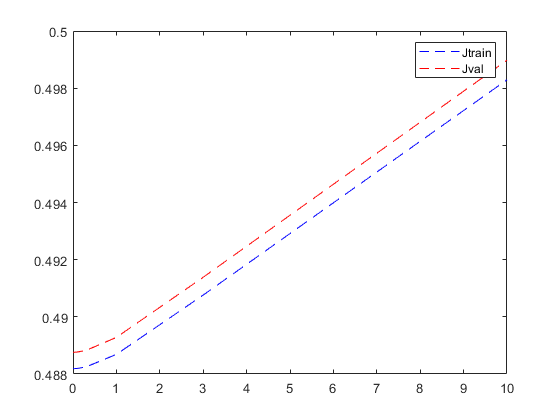

figure;
plot(lambda_vec,fitCost(:,1),'b--');
hold on;
plot(lambda_vec,fitCost(:,2),'r--');
legend('Jtrain','Jval');

This section calculates the learning curve.

lambda = 0;
fitCost = zeros(size(X,1),2);
for i=1:size(X,1)
    X_i = X(1:i,:);
    y_i = y(1:i);dw
    optim_theta = performLogisticReg(X_i,y_i,lambda);
    fitCost(i,1) = getCostFunction(optim_theta, [ones(size(X_i,1),1) X_i], y_i, 0);
    fitCost(i,2) = getCostFunction(optim_theta, [ones(size(Xval,1),1) Xval], yval, 0);
end


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>
Cost at theta found by fminunc: 0.000000

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

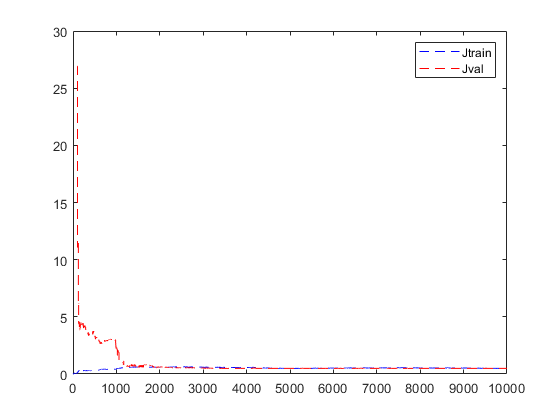

figure;
plot(1:size(X,1),fitCost(:,1),'b--');
hold on;
plot(1:size(X,1),fitCost(:,2),'r--');
legend('Jtrain','Jval');

### Neural Networks

[TODO]